# Introduction to Multiple Regression Models

[⇦ Main Menu](matlab:open('../../MainMenu.mlx'))

In this script, students explore multiple linear regression models and use real-world data to analyze and predict relationships between variables.

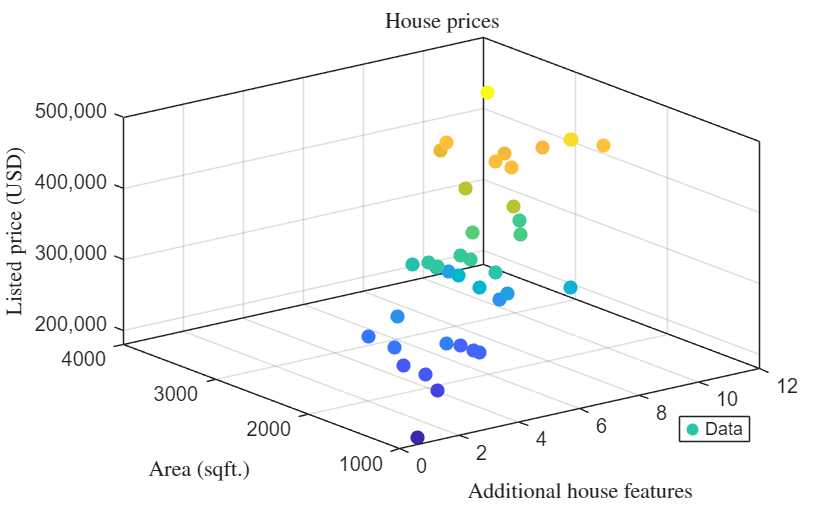

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View** tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**. Alternatively, select **Hide Code** using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2-hour online tutorial that teaches the essentials of MATLAB.

 For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The   and  icons refer to two different types of interactive activities that you will find in this script. The   usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## Multiple Linear Regression

Multiple regression is a statistical technique used to model the relationship between one dependent variable and two or more independent variables. It allows us to examine how the dependent variable changes when one independent variable varies, while the others are held constant.

A simple real-life example is microwaving food. The final temperature of the food (the dependent variable) depends on multiple factors, such as microwave time and power level (the independent variables). By adjusting time and power together, you influence how hot the food becomes. This mirrors the idea of multiple regression, where several inputs jointly affect an outcome.

When the relationship between the dependent variable and the independent variables is linear, meaning it can be expressed as a weighted sum of the predictors, the model is called a multiple linear regression model. Mathematically, it is often written as: If the model is linear in its coefficients, it is referred to as a multiple linear regression model.

$y =a_0+a_1x_1+a_2x_2+a_3x_3+...a_px_p$ ($\star\star$)

where $p$ is the number of explanatory variables and $a$ are the coefficients.

##  **Application. Heat Exchanger (Soft Sensor)**

We will start our journey into multiple regression with an example from chemical engineering. In many chemical engineering plants, the exchanger heat duty is approximated as:


$$Q\approx \dot{m} C_p \Delta T$$


where:

- $Q$ = heat duty (e.g., kW)

- $\dot{m}$ = mass flow rate (kg/s)

- $C_p$ = specific heat capacity (kJ/kg·°C)

- 
$$\Delta{T} = T_{\text{in}} - T_{\text{out}}$$


This equation is bilinear:

- linear in $\dot{m}$ if $\Delta{T}$ is fixed

- linear in $\Delta{T}$ if $\dot{m}$ is fixed

If you treat $C_p$ and $\Delta{T}$ as measured/controlled and keep the operation range narrow, a linear regression surrogate is a common “soft sensor” model used for monitoring and control, which is linear in its parameters:


$$Q=\beta_0+\beta_1 \dot m + \beta_2 \Delta T + \epsilon$$


You are a process engineer responsible for monitoring the heat duty ($Q$) of a liquid–liquid heat exchanger. Heat duty represents the rate of thermal energy transferred between the hot and cold streams and is commonly expressed in units of power (kW). Because direct measurement of heat duty is often noisy, expensive, or unavailable, you decide to build a soft sensor using readily available process transmitters such as flow rate and temperature measurements. Your goal is to build a regression model from the synthetic data set below. However, before trusting the model, you must validate the regression assumptions, especially linearity.

### Load and Plot Data

  **Try**. **Click the Load and Plot Data** to load the data for the heat duty ($Q$) as a function of mass flow rate($\dot{m}$) and the change in temperature($\Delta{T}$) as a table and as a scatter plot.

[mDot,dT,QkW,TT,~] = DataGen;
disp(TT(1:8,:))
 
figure
scatter3(mDot,dT,QkW,"filled",SeriesIndex=3,DisplayName="Data")

xlabel("$\dot{m}$ (kg/s)",Interpreter="latex")
ylabel("\Delta{T}(°C)",Interpreter="tex")
zlabel("Q (kW)",Interpreter="latex")
legend("show",Location="bestoutside")
box on
rotate3d on

ax = gca;
ax.ZAxis.Exponent = 0; % disable scientific notation
ztickformat("%,.0f") % show full integers

### View Data from Different Viewpoints

  **Try**. **Select a viewpoint** in the dropdown menu to explore how the data looks from different perspectives.

hold on
View =view(0,90); % Select a viewpoint from the dropdown menu.
hold off

 **Reflect**. What trends or patterns do you see in the data?

## Assumptions and Conditions of Linearity

So far, we have assumed our scatter plots show a straight-line relationship in simple [linear regression](matlab:open('./LinearRegressionSoln.mlx')). That’s easy to check with one predictor, but as we move to **multiple linear regression**, confirming linearity becomes critical. We can’t simply assume linearity, but we must verify it by checking whether the data truly follows a linear pattern.

Residual plots display residuals vs. fitted values, with a horizontal zero line which indicates perfect predictions. Instead of inspecting residuals individually, these plots provide an overall view of model performance by showing how far each point deviates from the model. Patterns such as curvature suggest nonlinearity, and changes in spread indicate unequal variance. By examining these features, we can assess whether the assumptions of linear regression hold and how well the model fits the data.

To evaluate these patterns systematically, we rely on a set of key assumptions that underpin linear regression.

- **Linearity Assumption:** The relationship between predictors and the response should be roughly linear.

- *Check 1:* Scatter plots of the response vs. each predictor should show an approximately straight-line pattern.

- *Check 2:* Residual plots should not display any clear patterns.

- **Independence Assumption:** Residuals (errors) should be independent of each other, with no autocorrelation.

- *Check:* Plot residuals against data-collection order, time, or run number and look for runs, drift, or clustering. Use residuals versus fitted values mainly to check linearity and equal variance, not independence.

- **Equal Variance (Homoscedasticity** (hoh-moh-suh-das-TISS-uh-tee)**):** Residual variance should be constant across fitted values.

- *Check:* Residuals vs. any of the predictors or the fitted values should show a consistent spread around the zero line, without fan or cone shapes.

- **Normality Assumption:** Residuals should be approximately normally distributed.

- ***Check 1:*** **Histogram of residuals should resemble a normal distribution.**

- ***Check 2:*** **In a probability plot of the residuals, the plotted points should fall roughly along a straight diagonal line, indicating that the observed residual probabilities are consistent with those expected under a normal distribution.**

Understanding and checking the **linearity**, **independence**, **equal variance**, and **normality assumptions** helps ensure that the regression model is valid and that its conclusions are trustworthy. When these conditions are reasonably satisfied, the full regression model can be used with confidence for interpretation and prediction.

  **Pro-tip**. When you see residual plots, pay close attention to the axes and the titles.

### Linearity Assumption

#### Preliminary Visual Assessment Using Scatter Plots

In simple linear regression, linearity can be assessed by examining a scatter plot of the response versus the single predictor and looking for an approximately straight-line pattern. In multiple regression, however, scatter plots of the response against each individual predictor are only a preliminary diagnostic, since they do not account for the effects of the other predictors in the model.

As an initial step, we examine scatter plots of the response against each predictor separately. These plots serve as a starting point to identify any obvious departures from linearity or unusual patterns before fitting the full regression model.

  **Try**. **Select a predictor** ($\dot{m}$ or $\Delta{T}$) from the dropdown menu to display the fitted model for $Q$ and the corresponding scatter plot for that predictor, then click **Display Model for Predictor**.

[mDot,dT,QkW,TT,t] = DataGen;
xVar = mDot;
 
if strcmp(xVar,"Select")
    warning("Select a valid option.")
    return
elseif isequal(xVar,mDot)
    xName = "Flow(" + "$\dot{m}$" + ")";
elseif isequal(xVar,dT)
    xName = "$\Delta T$";
else
    warning("Select a valid option.")
    return
end
yName = "Duty";
[~,gof] = createFit(xVar,QkW,xName,yName); %#ok<ASGLU>

#### **Linearity Assessment Using the Full Model and Residuals**

A more appropriate way to assess the linearity assumption is by examining residuals versus the predicted values. If the residual plots show random scatter around zero with no systematic patterns, the linearity assumption is reasonable. Curvature or other structured patterns would suggest that the linear form may be inadequate, in which case transformations, polynomial terms, or alternative models may be considered.

  **Try**. Click **View Residuals Plot** to view the residuals plot.

ResidualsPlot(dT,mDot,QkW,1,0,0,0);
 

### Independence Assumption

The **independence assumption** means the residuals (observed − predicted values) should not be related to each other. After the model accounts for the predictors, the remaining errors should look random, not connected across time, order, or groups (like the same machine, batch, subject, or day).

To check independence, plot residuals in the order the data were collected. Independence looks like residuals bouncing randomly around zero with no pattern. A few points close together are normal—random scatter often includes small groupings. Independence becomes a concern when you see repeated clusters, long runs of residuals mostly above or below zero, or clear **trends/cycles** over time, which can indicate correlation between observations.

  **Try**. Click **Evaluate Independence Assumption** to display the data table, and to view the sequenced residuals plot.

[mDot,dT,QkW,TT,t] = DataGen;
disp(TT)
 
ResidualsPlot(dT,mDot,QkW,0,0,1,0);

 **Reflect**. Do the residual plots show any patterns, trends, or clusters?

### **Equal Variance Assumption or Homoscedasticity**

**Equal variance**, also called **homoscedasticity**, means that the spread of the residuals remains approximately constant across all fitted values. In other words, the variability of the errors does not systematically increase or decrease as the predicted response changes.

To assess equal variance, we examine a plot of residuals versus fitted values. When the assumption holds, the residuals form a roughly uniform horizontal band centered around zero, with a similar spread across all fitted values.

This assumption is violated when the residual variability changes as fitted values increase or decrease. In these cases, the residuals may spread out or narrow, producing a characteristic fan or funnel shape in the residual plot, which indicates non-constant variance.

In the figures below, the **left plot** illustrates equal variance, with residuals evenly scattered around zero across the range of fitted values. The **right plot** shows unequal variance, where the residuals display a funnel-shaped pattern, indicating that the variability changes with the fitted values.

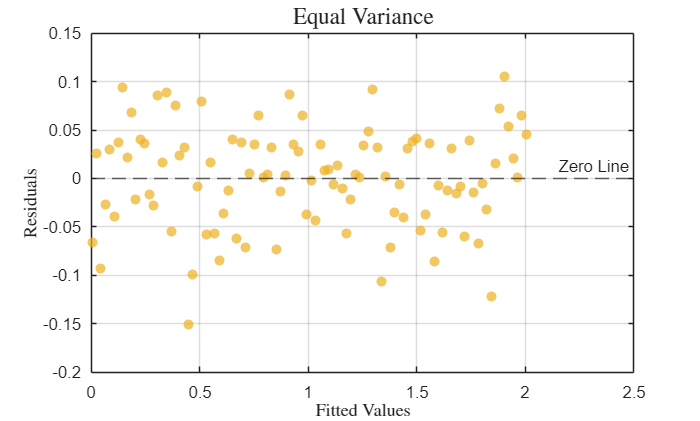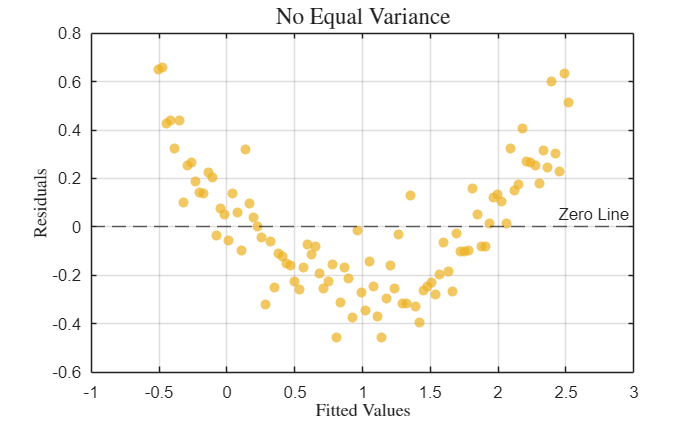

  **Try**. Click **Evaluate Homoscedasticity Assumption** to evaluate the residuals plot to check that the variability of residuals is constant.

 
ResidualsPlot(mDot,dT,QkW,1,0,0,0);

 **Reflect**. Are residuals randomly scattered around, or do they cluster or curve away from the zero line in a systematic shape like a fan or a cone? 

### Normality Assumption

#### View Histogram

The normality assumption requires that the residuals follow an approximately normal distribution. As an initial check, we examine a histogram of the residuals. If the histogram appears roughly symmetric and bell‑shaped, this provides preliminary evidence that the normality assumption is reasonable. Large departures from symmetry or the presence of heavy tails may indicate potential violations of normality.

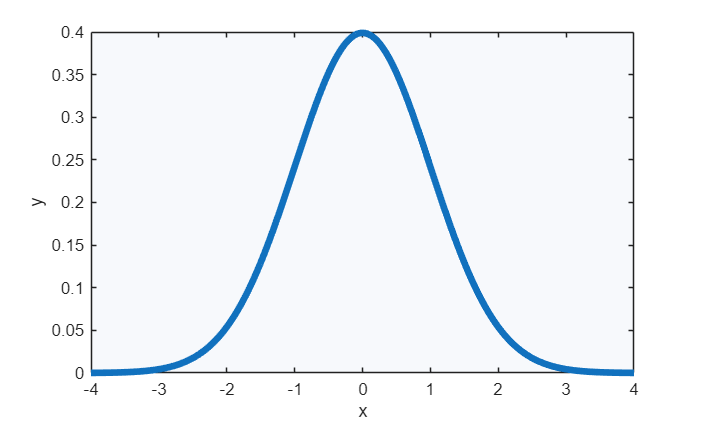

  **Try**. Click **View Histogram** to view the histogram of the residuals. 

 
ResidualsPlot(mDot,dT,QkW,0,1,0,0);

#### View Probability Plot

To further assess normality, we examine a normal probability plot of the residuals. In this plot, the ordered residuals are compared to what would be expected if they followed a normal distribution. If the residuals are approximately normal, the points will fall close to the reference line. Systematic deviations from the line, such as curvature or extreme outliers, suggest that the normality assumption may not hold.

  **Try**. Click **View Probability Plot** to view the probability plot. 

 
ResidualsPlot(mDot,dT,QkW,0,0,0,1);

 **Reflect**. Based on the histogram of the residuals and the probability plot of the residuals, does the data appear to be normal? After checking **linearity**, **independence**, **equal variance**, and **normality of residuals**, do the assumptions appear sufficiently satisfied to proceed with the regression model for the **soft sensor**? Why or why not?

### Evaluate Linearity Assumptions for Synthetic Data

Refer to the Assumptions and Conditions of Linearity section and determine for each of the three data sets below if they are linear.

  **Try**. Determine whether each dataset is linear or nonlinear.

- **Select a dataset** from the dropdown menu.

- Click **Check Linearity Assumptions** to step through each check of the linearity assumptions.

Choice = "Data 2";

if ~strcmp(Choice,"Select")
    [x1,x2,y] = Dataset(Choice);
    % Persistent or stored step count
    if exist("StepCount","var")
        StepCount = StepCount;
    else
        StepCount = 0;
    end

    % Run one step
    StepCount = runDiagnosticStep(x1,x2,y,"$x_1$","$x_2$","y",StepCount); %#ok<NASGU>
     
else
    warning("Select a valid option.")
    return
end

### Reset Linearity Assumption Check

  **Try**. Click **Restart Linearity Assumptions to 1A** to reset the linearity assumptions.

StepCount = resetDiagnosticSteps();
 

### Which Datasets are Linear?

 **Exercise 1**. Check the **check** **boxes** for the datasets you believe are linear, then click **Check Answer**.

Answer = [true,true,false];
CheckAnswer(Answer)
 

## Practice Applying Assumptions of Linearity to Housing Price Data

In [Linear Regression](matlab:open('./LinearRegression.mlx')), we evaluated the housing price vs. square footage. While using square footage alone to predict home prices is a helpful starting point, it does not capture the full complexity of what determines a home's value. This limitation arises because simple regression focuses on only one independent variable. As a result, it cannot account for the many other factors that influence price. **Multiple regression** addresses this issue by allowing us to include several independent variables in the model. By adding features such as the number of appliances, modern upgrades, or other special amenities, we can create a more accurate and realistic model that better explains the variation in home prices.

 **Application.** Let's examine the linearity assumptions for housing prices data. 

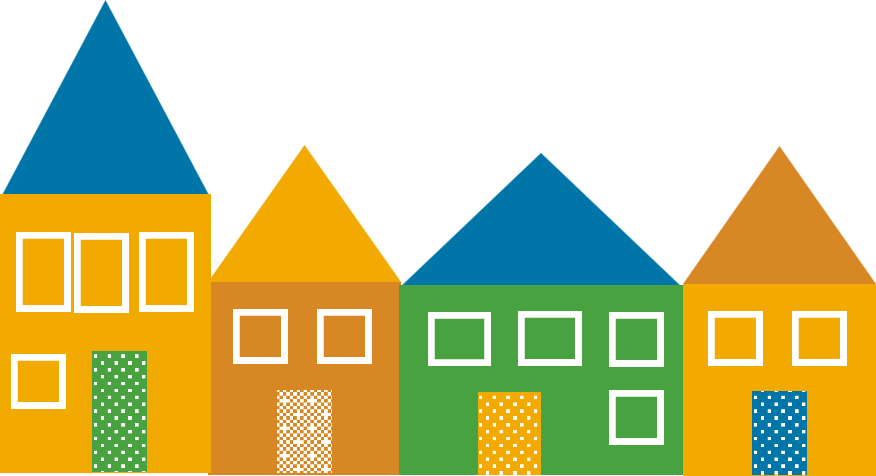

### Load and Examine the Data

  **Try**. Click **Load and Plot Data** to load and plot the house price data.

 
load MultivariateData.mat x1 x2 y

figure
scatter3(x1,x2,y,36,"o","filled") % Plot the data points
xlabel("Additional house features",Interpreter="latex") % Label the axes
ylabel("Area (sqft.)",Interpreter="latex")
zlabel("Listed price (USD)",Interpreter="latex")

legend("Data",Location="northwest")
title("House prices",Interpreter="latex") % Add a title

  **Pro-tip**. Click on the figure of the 3D graph and then click the Expand axes toolbar button see its toolbar. icon. Clicking the Rotate 3D   button in the axes toolbar to manually rotate the graph into different viewpoints.

rotate3d on

### Reset Linearity Assumption Check

  **Try**. Click the **Restart Linearity Assumptions to 1A** to reset the linearity assumptions.

StepCount = resetDiagnosticSteps();
 

### Evaluate Linearity Assumptions for House Data

Refer to the Assumptions and Conditions of Linearity section and determine for each of the three data sets below if they are linear. Determine whether the dataset for the housing data is linear or meets the conditions of linearity.

  **Try**. Click **Check the Linearity Assumptions** to evaluate the linearity assumptions for the house price data.

[x1,x2,y] = Dataset("House"); %#ok<ASGLU>
% Run one step
StepCount = runDiagnosticStep(x1,x2,y,"Features","Sqft","Price",StepCount);
 

## Perform Multiple Regression

In **multiple linear regression** with $p$ independent variables, the model takes the form $y =a_0+a_1x_1+a_2x_2+a_3x_3+...a_px_p$, which represents a plane in ($p+1$)-dimensional space. Plotting this plane alongside the data points allows you to visually assess how well the model fits the data. It helps us understand the influence of how changes in each of the coefficients affect the plane's orientation and position. This visualization also reveals whether the relationship between variables is truly linear and can highlight patterns, clusters, or outliers that may suggest the need for a more complex model.

In [Linear Regression](matlab:open('./LinearRegressionSoln.mlx')), we discussed using the sum of squared errors (SSE) which is calculated by squaring each residual and summing them across all observations. Here, we also introduce the root mean squared error (RMSE), which takes the square root of the average of the squared errors. SSE reflects the total accumulated error, whereas RMSE expresses the typical size of an error in the same units as the outcome, helping distinguish between cumulative error and per-observation performance.

  **Try**. Click **Generate a Plane of Coefficients** to open an app that allows you to adjust sliders for the coefficients and visualize the residuals to attain the optimal fit. 

- Check **Show Residuals**.

- Check **Show Regression Plane**.

- Check **Rotate 3D**.

- Drag the sliders for the coefficients to attain the optimal fit.

- Click **Show Optimal** to display the optimal coefficients, **Randomize** to generate new coefficient values, and **Reset** to restore the default coefficients.

  **Pro-tip**. The app will show the root mean squared error (RMSE) and the sum of the squared errors (SSE). Compare the magnitude of these values to further understand why we use SSE.

 
InteractiveHouseModel

 **Reflect**. How easy or difficult was it to find the best coefficients to describe the model? How did you determine that the coefficients you chose created a good fit?

 **Exercise 2.** You would like to find a 2342 sqft. house with 7 additional features. How much will you pay for this home?

We can use Equation ($\star\star$) to obtain the equation for the house price as a function of features and square footage, where 

- $\text{NumFeat}$ is the number of features, $x_1$

- $\text{Sqft}$ is the square footage or area, $x_2$

- $\text{PriceAdd}$ is the home price, $y$

- $a_1$ is the price per feature

- $a_2$ is the price per square foot

- $a_0$ is the base price

Please enter your `PriceAdd` as a function of `a0,a1,a2,NumFeat,Sqft`.

NumFeat = 7;
Sqft = 2342;
load MultivariateData.mat x1 x2 y; % Load the data if variables do not exist
[xData,yData,zData] = prepareSurfaceData(x1,x2,y);
[fitresult,gof] = fit([xData,yData],zData,"poly11");
a0 = fitresult.p00;
a1 = fitresult.p10;
a2 = fitresult.p01;
try
    [EqnFunc,TrueAns] = CheckVariables("a1*NumFeat+a2*Sqft+a0");
catch
    warning("Enter MATLAB code.")
    return
end
if TrueAns == 1
    PriceVal = round(EqnFunc(a0,a1,a2,NumFeat,Sqft));
    CheckAns(TrueAns,PriceVal)
else
    warning("Enter MATLAB code above.")
end
 

## Bringing It All Together: Why These Checks Matter

At this point, it’s worth stepping back to ask: Was all of this linearity checking worth the time?

Yes—because these checks tell you how to improve the model, not just whether it “works.”

Linearity diagnostics help answer a basic question: Is a straight‑line relationship reasonable for this predictor? If the linearity assumption looks weak, the predictor may still be useful—but it may need a different representation. In other words, the linearity checks point directly to feature engineering choices, such as:

- applying a feature transformation (e.g., log, square root, inverse),

- adding curvature (e.g., polynomial terms),

- including interactions (when one predictor’s effect depends on another),

- modeling piecewise behavior, or

- re‑expressing a variable (scaling/units or a more meaningful representation).

In practice, many people fit the multiple regression first and use predictor p‑values as a quick screen. For example, when you use [`fitlm`](https://www.mathworks.com/help/stats/fitlm.html), you can obtain a p‑value for each predictor from the model’s coefficient table. Large p‑values can flag predictors that contribute little *in the current linear form*, but they don’t explain whether a predictor is truly irrelevant or simply misspecified (e.g., nonlinear or interacting). That’s why the linearity checks matter: they guide the **feature engineering** you may need before deciding what to keep.

Even when both the overall ANOVA p‑value and the individual predictor p‑values are low, it is still worth doing the linearity checks. Low p‑values tell you that the model has signal and that the predictors contribute information under a linear formulation, but they do not tell you whether the linear form you chose is appropriate. A predictor can be statistically significant and still be poorly modeled if the true relationship is nonlinear, involves interactions, or shows systematic patterns in the residuals. Linearity checks help you determine whether the model is capturing the relationship in a reasonable way or whether feature engineering—such as transformations, added curvature, or interactions—could improve the model. In this sense, significance answers *whether* something is happening, while linearity checks help you understand *how* it should be modeled.

 **Reflect**. Why are linearity checks worth doing if you can already look at p‑values after fitting the model? What important information do p‑values alone fail to provide?

## Try Multiple Regression on Your Own

Learn how to import a dataset in MATLAB, evaluate linearity, and build multiple regression models in [Practice Multiple Regression](matlab:open('./TryMultipleSoln.mlx')).

## Glossary

**Feature Engineering**: changing how predictors enter the model so the linear regression assumptions are more reasonable. (↑ Return to Text)

**Residuals Plot**: a plot that displays residuals on the y‑axis against the model’s fitted values on the x‑axis, with a horizontal zero line indicating perfect predictions. (↑ Return to Text)

**Multiple Regression:** a regression technique that uses two or more independent variables to predict a single dependent variable. (↑ Return to Text)

## References

[How to pronounce homoscedasticity](https://dictionary.cambridge.org/us/pronunciation/english/homoscedasticity), Cambridge Dictionary.

### Further Exploration

Review the [Additional Resources](matlab:open('../AdditionalResources.mlx')) section to find more materials for further learning.

[⇦ Return to the Main Menu](matlab:open('../../MainMenu.mlx'))

## Local Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline** using the icon   at the top right of the Live Editor pane.

function InteractiveHouseModel
launchInteractiveHouseModelApp();
end

function CheckAnswer(Answer)
if isequal(Answer,[1,1,0])
    disp("You are correct.")
elseif isequal(Answer,[0,0,0])
    warning("Select at least one checkbox")
else
    disp("Have you selected all of the linear datasets?")
end
end

function [X1,X2,Y] = GenerateData(beta0,beta1,beta2)
% Number of observations
n = 50;

% Generate synthetic predictors with a stronger correlation
X1 = randn(n,1); % Predictor 1
X2 = 2 *X1 + 0.1 * randn(n,1); % Predictor 2 with reduced noise for stronger correlation


% Generate synthetic response variable with minimal noise
noise = 0.01 * randn(n,1); % Further reduced random noise
Y = beta0 + beta1 * X1 + beta2 * X2 + noise;
end

function [x1,x2,y] = Dataset(Choice)
switch Choice
    case "House"
        load MultivariateData.mat x1 x2 y;
    case "Data 1"
        [x1,x2,y] = GenerateData(5,-3,2);
    case "Data 2"
        [x1,x2,y] = GenerateData(5,-2,-1);
    case "Data 3"
        % Generate synthetic predictors with a stronger correlation
        x1 = randn(50,1); % Predictor 1
        x2 = 2 * x1 + 0.1 * randn(50,1); % Predictor 2 with reduced noise for stronger correlation

        % Generate synthetic response variable with nonlinear relationship
        noise = 0.01 * randn(50,1); % Further reduced random noise
        y = 2 + 4 * x1 + -3 * x2 + 0.5 * x1.^2 + noise; % Added nonlinearity with X1^2
end
disp(Choice + " Dataset loaded.")
end

function ResidualsPlot(x1,x2,y,ResidFit,ResidHist,ResidOrd,ResidProbPlot)
% ResidualsPlot: Plot residuals versus fitted values for a multiple linear model
arguments
    x1 (:,1) double
    x2 (:,1) double
    y  (:,1) double
    ResidFit (1,1) logical = false
    ResidHist (1,1) logical = false
    ResidOrd (1,1) logical = false
    ResidProbPlot (1,1) logical = false
end

% Fit multiple linear regression model
mdl = fitlm([x1 x2],y);

% Extract fitted values and residuals
fittedVals = mdl.Fitted;
residuals = mdl.Residuals.Raw;

if ResidFit
    % Plot residuals vs fitted
    figure
    scatter(fittedVals,residuals,36,"filled",SeriesIndex=3,MarkerFaceAlpha=0.7)

    hold on
    yline(0,"--","Zero Line",HandleVisibility="off")
    xlabel("Fitted Values",Interpreter="latex")
    ylabel("Residuals",Interpreter="latex")
    title("Residuals vs. Fitted",Interpreter="latex")
    grid on
    box on
    hold off
end

if ResidHist
    % Create histogram
    figure
    h = histogram(residuals,10,"Normalization","probability",FaceColor=[0.2 0.6 0.8],EdgeColor=[0.1 0.1 0.1]); %#ok<NASGU>

    xlabel("Residual Value",Interpreter="latex")
    ylabel("Relative Frequency",Interpreter="latex")
    title("Histogram of Residuals",Interpreter="latex")
    grid on
    box on
end

if ResidOrd
    n = numel(residuals);

    figure
    scatter(1:n,residuals,36,"filled",SeriesIndex=4)

    hold on
    yline(0, "--","Zero Line",LineWidth=1.2)
    hold off

    xlabel("Observation Number",Interpreter="latex")
    ylabel("Residual",Interpreter="latex")
    title("Residuals (Case Order)",Interpreter="latex")
    grid on
    box on
end

if ResidProbPlot
    % Sort residuals
    rSorted = sort(residuals);
    n = numel(rSorted);

    % Theoretical normal quantiles
    p = ((1:n)' - 0.5) / n;
    mu = mean(rSorted);
    sigma = std(rSorted);
    q = norminv(p,mu,sigma);

    % Plot
    figure
    scatter(q,rSorted,36,"filled",SeriesIndex=5)
    hold on

    % Reference line (least-squares fit line)
    xLine = [min(q),max(q)];
    yLine = mu + sigma * (xLine - mean(q)) / std(q);
    plot(xLine,yLine,"-",LineWidth=1.5,SeriesIndex="none")

    hold off

    xlabel("Residuals",Interpreter="latex")
    ylabel("Probability",Interpreter="latex")
    title("Normal Probability Plot of Residuals",Interpreter="latex")

    grid on
    box on
end
end


function [EqnFunc,TrueAns] = CheckVariables(EquationStr)
arguments
    EquationStr (1,1) string % Must be a single string
end

% Initialize outputs
EqnFunc = [];
TrueAns = 0;

% Early exit if user has not entered code
if strcmpi(strtrim(EquationStr),"Enter MATLAB code.")
    warning("Enter MATLAB code.")
    return
else
    varPattern = pattern("a0"|"a1"|"a2"|"NumFeat"|"Sqft");
    variablesToCheck = ["a0","a1","a2","NumFeat","Sqft"];
    EqnFunc = str2func("@(a0,a1,a2,NumFeat,Sqft)" + EquationStr);
end

% Extract variables from equation string
vars = extract(EquationStr,varPattern);

% Default answer
TrueAns = 1;

% Check presence of variables
for var = variablesToCheck
    Occurs = sum(strcmp(vars,var));
    if Occurs == 0
        warning("The variable '%s' is not present.",var);
        TrueAns = 0;
    end
end
end

function CheckAns(TrueAns,userResult) % function to calculate value if all variables are present

if TrueAns == 1
    TrueVal = 322238;
end

if abs(userResult - TrueVal) < 1 % Compare to true value
    disp(" You are correct.")
else
    disp("You are incorrect. Please check your calculations.")
    return
end
end

function [mDot,dT,QkW,TT,t] = DataGen
%% Synthetic CHE time-series: Clean linear scatter + clean case-order residuals
rng shuffle

% Time base: 2 hours at 1-min sampling (121 points)
t = (datetime(2026,1,1,8,0,0):minutes(1):datetime(2026,1,1,10,0,0))';
n = numel(t);

% Continuous predictors every minute (no regimes, no drift)
mDot = 1.30 + 0.22*randn(n,1); % kg/s
dT = 20.0 + 2.60*randn(n,1); % °C

% Soft bounds (rarely hit)
mDot = max(0.8, min(mDot, 1.9));
dT   = max(12,min(dT,28));

% Linear duty model
beta0 = 5;
beta1 = 65;
beta2 = 12;

sigma = 0.9; % measurement noise
QkW = beta0 + beta1*mDot + beta2*dT + sigma*randn(n,1);

TT = timetable(t,QkW,mDot,dT);
t =TT.t;
mDot=TT.mDot;
QkW=TT.QkW;
dT= TT.dT;
end

function [fitresult,gof] = createFit(x,y,xName,yName)

arguments
    x (:,1) double
    y (:,1) double
    xName (1,1) string = "x"
    yName (1,1) string = "y"
end

% Prepare data
[xData,yData] = prepareCurveData(x,y);

% Fit linear model (for coefficients + GOF only)
[fitresult,gof] = fit(xData,yData,"poly1");

% Evaluate fitted line
xFit = linspace(min(xData),max(xData),200);
yFit = feval(fitresult,xFit);

legName = yName + " vs. " + xName;
figure
scatter(xData,yData,36,"filled",DisplayName="Data",SeriesIndex=3)
hold on
plot(xFit,yFit,"LineWidth",2,DisplayName="Fit",SeriesIndex="none")
hold off

xlabel(xName,Interpreter="latex")
ylabel(yName,Interpreter="latex")

title("Linear Fit of " + legName,Interpreter="latex")

legend("show",Location="bestoutside")

grid on
box on

% — FORCE NORMAL NOTATION ON X-AXIS —
ax = gca;
ax.YAxis.Exponent = 0; % disable scientific notation
ytickformat("%,.0f") % show full integers
end

function StepCount = runDiagnosticStep(x1,x2,y,xName1,xName2,yName,StepCount)
% runDiagnosticStep  Advance and execute the next diagnostic step

arguments
    x1 (:,1) double
    x2 (:,1) double
    y (:,1) double
    xName1 (1,1) string
    xName2 (1,1) string
    yName (1,1) string
    StepCount (1,1) double {mustBeInteger, mustBeNonnegative}
end

% Advance StepCount
StepCount = StepCount + 1;

switch StepCount
    case 1
        createFit(x1,y,xName1,yName);
        if xName1 == "$x_1$"
            xName1 = "x_1";
        end
        displayFormula(['"Linearity Assumption Check 1A: Does "', "yName", '" vs. "' ,xName1, '" look straight-enough?"'])

    case 2
        createFit(x2,y,xName2,yName);
        if xName2 == "$\Delta{T}$"
            xName2 = "Delta*T";
        end
        if xName2 == "$x_2$"
            xName2 = "x_2";
        end
        displayFormula(['"Linearity Assumption Check 1B: Does "', "yName", '" vs. "' ,xName2,  '" look straight-enough?"'])
    case 3
        ResidualsPlot(x1,x2,y,true,false,false,false);
        displayFormula('"Linearity Assumption Check 2: Do residuals vs fitted look random?"')
    case 4
        ResidualsPlot(x1,x2,y,false,false,true,false);
        displayFormula('"Independence Assumption: Residuals in collection order look random?"');
    case 5
        ResidualsPlot(x1,x2,y,true,false,false,false);
        displayFormula('"Equal Variance: Roughly constant residual spread?"');
    case 6
        ResidualsPlot(x1,x2,y,false,true,false,false);
        displayFormula('"Normality Check 1: Histogram roughly symmetric centered near zero?"');
    case 7
        ResidualsPlot(x1,x2,y,false,false,false,true);
        displayFormula('"Normality Check 2: Probability plot points near reference line?"');
    otherwise
        StepCount = 0;
        displayFormula('"All steps complete. Resetting step counter."')
end
end

function StepCount = resetDiagnosticSteps()
StepCount = 0;
disp("Linearity Assumptions reset.")
end

function fig = launchInteractiveHouseModelApp
% launchInteractiveHouseModelApp Open the regression-basics house-model app.

try
    projectRoot = fileparts(fileparts(mfilename("fullpath")));
    dataFile = fullfile(projectRoot,"Data","MultivariateData.mat");
    S = load(dataFile,"x1","x2","y");
    x1 = S.x1;
    x2 = S.x2;
    y = S.y;
catch
    rng(42,"twister")
    n = 100;
    x1 = 1 + 4*rand(n,1);
    x2 = 500 + 2000*rand(n,1);
    truea1 = 7500;
    truea2 = 250;
    truea0 = 6000;
    y = truea1*x1 + truea2*x2 + truea0 + 20000*randn(n,1);
end

X = [ones(length(x1),1),x1,x2];
optimalCoeffs = X \ y;
a0Opt = optimalCoeffs(1);
a1Opt = optimalCoeffs(2);
a2Opt = optimalCoeffs(3);
optimalSSE = sum((y - (a1Opt*x1 + a2Opt*x2 + a0Opt)).^2);
baselineSSE = sum((y - mean(y)).^2);

a1Limits = expandSliderLimits([1000 150000],a1Opt,1000);
a2Limits = expandSliderLimits([5 200],a2Opt,25);
a0Limits = expandSliderLimits([5000 150000],a0Opt,5000);
initialView = [-150 25];
maxPoorFitTries = 50;

[a1,a2,a0] = randomPoorCoefficients();
referenceSSE = baselineSSE;
theme = houseModelTheme();

fig = uifigure(Name="Interactive House Price Model - 3D Linear Regression", ...
    Position=[100 100 1200 700]);

mainGrid = uigridlayout(fig,[2,3]);
mainGrid.ColumnWidth = {300,"1x",250};
mainGrid.RowHeight = {"1x",80};

leftPanel = uipanel(mainGrid,Title="Model Parameters",FontWeight="bold");
leftPanel.Layout.Row = 1;
leftPanel.Layout.Column = 1;

controlGrid = uigridlayout(leftPanel,[12,1]);
controlGrid.RowHeight = {"fit","fit","fit","fit","fit","fit","fit","fit","fit","fit","fit","1x"};
controlGrid.Padding = [15 15 15 15];
controlGrid.RowSpacing = 8;

instructLabel = uilabel(controlGrid, ...
    Text=(" Adjust the sliders to find the best linear model!" + newline + ...
    "Try to minimize the residuals."), ...
    FontWeight="bold",FontColor=theme.InstructionColor, ...
    WordWrap="on");
instructLabel.Layout.Row = 1;

a1TitleLabel = uilabel(controlGrid,Text="Price per Additional Feature", ...
    FontWeight="bold",FontColor=theme.FeatureColor);
a1TitleLabel.Layout.Row = 2;
a1ValueLabel = uilabel(controlGrid,Text="$" + formatWholeNumber(a1) + " per feature", ...
    FontColor=theme.FeatureValueColor);
a1ValueLabel.Layout.Row = 3;

a1Ticks = sliderTicks(a1Limits,50000);
a1Slider = uislider(controlGrid, ...
    Limits=a1Limits, ...
    Value=a1, ...
    MajorTicks=a1Ticks, ...
    MajorTickLabels=intWithCommas(a1Ticks));
a1Slider.Layout.Row = 4;

a2TitleLabel = uilabel(controlGrid,Text="Price per Square Foot", ...
    FontWeight="bold",FontColor=theme.AreaColor);
a2TitleLabel.Layout.Row = 5;
a2ValueLabel = uilabel(controlGrid,Text="$" + formatWholeNumber(a2) + " per sqft.");
a2ValueLabel.Layout.Row = 6;

a2Ticks = sliderTicks(a2Limits,50);
a2Slider = uislider(controlGrid, ...
    Limits=a2Limits, ...
    Value=a2, ...
    MajorTicks=a2Ticks, ...
    MajorTickLabels=intWithCommas(a2Ticks));
a2Slider.Layout.Row = 7;

a0TitleLabel = uilabel(controlGrid,Text="Base House Price", ...
    FontWeight="bold",FontColor=theme.BasePriceColor);
a0TitleLabel.Layout.Row = 8;
a0ValueLabel = uilabel(controlGrid, ...
    Text="$" + formatWholeNumber(a0) + " base");
a0ValueLabel.Layout.Row = 9;

a0Ticks = sliderTicks(a0Limits,50000);
a0Slider = uislider(controlGrid, ...
    Limits=a0Limits, ...
    Value=a0, ...
    MajorTicks=a0Ticks, ...
    MajorTickLabels=intWithCommas(a0Ticks));
a0Slider.Layout.Row = 10;

equationLabel = uilabel(controlGrid, ...
    Text=currentModelText(a1,a2,a0), ...
    FontWeight="bold", ...
    WordWrap="on");
equationLabel.Layout.Row = 11;

ax = uiaxes(mainGrid);
ax.Layout.Row = 1;
ax.Layout.Column = 2;
ax.Title.String = " House Price Model Visualization";
ax.Title.FontSize = 14;
ax.XLabel.String = "Additional Features (#)";
ax.YLabel.String = "House Area (sqft.)";
ax.ZLabel.String = "Listed Price (USD)";
ax.FontSize = 10;
view(ax,initialView);
grid(ax,"on");
ax.GridAlpha = 0.3;
defaultInteractions = ax.Interactions;

rightPanel = uipanel(mainGrid,Title="Model Controls",FontWeight="bold");
rightPanel.Layout.Row = 1;
rightPanel.Layout.Column = 3;

statsGrid = uigridlayout(rightPanel,[10,1]);
statsGrid.RowHeight = {
    30,...
    30,...
    "fit",...
    "fit",...
    "fit",...
    "fit",...
    "fit",...
    "fit",...
    "fit",...
    "fit"};
statsGrid.Padding = [15 15 15 15];
statsGrid.RowSpacing = 6;

RMSELabel = uilabel(statsGrid,Text="RMSE: $",FontWeight="bold");
RMSELabel.Layout.Row = 1;
SSELabel = uilabel(statsGrid,Text="SSE: ",FontWeight="bold");
SSELabel.Layout.Row = 2;

sepLabel = uilabel(statsGrid,Text="---------------",HorizontalAlignment="center");
sepLabel.Layout.Row = 3;

showOptimalBtn = uibutton(statsGrid,Text="Show Optimal", ...
    BackgroundColor=theme.OptimalButtonColor, ...
    FontColor=theme.OptimalButtonTextColor, ...
    FontWeight="bold", ...
    ButtonPushedFcn=@showOptimalCallback);
showOptimalBtn.Layout.Row = 4;

randomizeBtn = uibutton(statsGrid,Text="Randomize", ...
    BackgroundColor=theme.RandomizeButtonColor, ...
    FontColor=theme.RandomizeButtonTextColor, ...
    FontWeight="bold", ...
    ButtonPushedFcn=@randomizeCallback);
randomizeBtn.Layout.Row = 5;

resetBtn = uibutton(statsGrid,Text="Reset", ...
    BackgroundColor=theme.ResetButtonColor, ...
    FontColor=theme.ResetButtonTextColor, ...
    FontWeight="bold", ...
    ButtonPushedFcn=@resetCallback);
resetBtn.Layout.Row = 6;

visLabel = uilabel(statsGrid,Text="Visualization Options:",FontWeight="bold");
visLabel.Layout.Row = 7;

showResidualsCheck = uicheckbox(statsGrid,Text="Show Residuals", ...
    Value=false,ValueChangedFcn=@(~,~) updateVisualization());
showResidualsCheck.Layout.Row = 8;

showPlaneCheck = uicheckbox(statsGrid,Text="Show Regression Plane", ...
    Value=false,ValueChangedFcn=@(~,~) updateVisualization());
showPlaneCheck.Layout.Row = 9;

rotate3DCheck = uicheckbox(statsGrid,Text="Rotate 3D", ...
    Value=false,ValueChangedFcn=@rotate3DCallback);
rotate3DCheck.Layout.Row = 10;

bottomGrid = uigridlayout(mainGrid,[1,3]);
bottomGrid.Layout.Row = 2;
bottomGrid.Layout.Column = [1 3];
bottomGrid.ColumnWidth = {"1x","fit","fit"};

feedbackLabel = uilabel(bottomGrid, ...
    Text="Adjust the parameters to improve your model fit!", ...
    FontWeight="bold",FontColor=theme.ScoreColor);
feedbackLabel.Layout.Column = 1;

scoreLabel = uilabel(bottomGrid, ...
    Text="Model Score: %", ...
    FontWeight="bold",FontColor=theme.ScoreColor);
scoreLabel.Layout.Column = 2;

congratsLabel = uilabel(bottomGrid, ...
    Text="", ...
    FontWeight="bold",FontColor=theme.SuccessColor);
congratsLabel.Layout.Column = 3;

a1Slider.ValueChangingFcn = @(~,~) sliderCallback();
a2Slider.ValueChangingFcn = @(~,~) sliderCallback();
a0Slider.ValueChangingFcn = @(~,~) sliderCallback();

toggleRotate3D(rotate3DCheck.Value);
drawnow
resetChallenge(a1,a2,a0)

    function sliderCallback(varargin)
        a1ValueLabel.Text = "$" + formatWholeNumber(a1Slider.Value) + " per feature";
        a2ValueLabel.Text = "$" + formatWholeNumber(a2Slider.Value) + " per sqft.";
        a0ValueLabel.Text = "$" + formatWholeNumber(a0Slider.Value) + " base";
        equationLabel.Text = currentModelText(a1Slider.Value,a2Slider.Value,a0Slider.Value);
        updateVisualization();
    end

    function updateVisualization()
        a1Curr = a1Slider.Value;
        a2Curr = a2Slider.Value;
        a0Curr = a0Slider.Value;

        currentView = ax.View;
        delete(ax.Children);
        hold(ax,"off");

        x1Range = linspace(min(x1)-0.2,max(x1)+0.2,30);
        x2Range = linspace(min(x2)-50,max(x2)+50,30);
        [X1Mesh,X2Mesh] = meshgrid(x1Range,x2Range);
        YPredMesh = a1Curr*X1Mesh + a2Curr*X2Mesh + a0Curr;

        if showPlaneCheck.Value
            surf(ax,X1Mesh,X2Mesh,YPredMesh, ...
                FaceAlpha=0.3,FaceColor=theme.SurfaceColor,EdgeColor="none");
            hold(ax,"on");
        end

        yPred = a1Curr*x1 + a2Curr*x2 + a0Curr;
        residuals = y - yPred;

        scatter3(ax,x1,x2,y,60,"filled", ...
            MarkerFaceAlpha=0.9, ...
            MarkerEdgeColor="none", ...
            SeriesIndex=theme.ObservedSeries);
        hold(ax,"on");

        if showResidualsCheck.Value
            for i = 1:length(x1)
                if residuals(i) >= 0
                    residualSeries = theme.PositiveResidualSeries;
                else
                    residualSeries = theme.NegativeResidualSeries;
                end

                plot3(ax, ...
                    [x1(i) x1(i)], ...
                    [x2(i) x2(i)], ...
                    [y(i) yPred(i)], ...
                    SeriesIndex=residualSeries, ...
                    LineWidth=1.5);
            end
        end

        hold(ax,"off");
        ax.View = currentView;

        RMSE = sqrt(mean(residuals.^2));
        SSE = sum(residuals.^2);
        RMSELabel.Text = "RMSE($): " + formatWholeNumber(RMSE);
        SSELabel.Text = "SSE($^2): " + formatWholeNumber(SSE);

        score = scoreFromSSE(SSE);
        scoreLabel.Text = sprintf("Model Score: %.1f%%",score);

        if score > 90
            feedbackLabel.Text = "Excellent fit! You're close to the true model.";
            feedbackLabel.FontColor = theme.SuccessColor;
            congratsLabel.Text = "Nice work.";
        elseif score > 60
            feedbackLabel.Text = "Good fit. Try adjusting parameters slightly.";
            feedbackLabel.FontColor = theme.WarningColor;
            congratsLabel.Text = "";
        else
            feedbackLabel.Text = "Poor fit. Keep tuning the model.";
            feedbackLabel.FontColor = theme.AlertColor;
            congratsLabel.Text = "";
        end

        drawnow limitrate
    end

    function showOptimalCallback(~,~)
        try
            setCoefficients(a1Opt,a2Opt,a0Opt);
        catch ME
            disp(getReport(ME,"extended"))
            uialert(fig,ME.message,"Optimal Button Error");
        end
    end

    function randomizeCallback(~,~)
        [a1Rand,a2Rand,a0Rand] = randomCoefficients();
        setCoefficients(a1Rand,a2Rand,a0Rand);
    end

    function resetCallback(~,~)
        [a1Reset,a2Reset,a0Reset] = randomPoorCoefficients();
        resetChallenge(a1Reset,a2Reset,a0Reset);
    end

    function setCoefficients(a1Value,a2Value,a0Value)
        a1Slider.Value = clampToLimits(a1Value,a1Slider.Limits);
        a2Slider.Value = clampToLimits(a2Value,a2Slider.Limits);
        a0Slider.Value = clampToLimits(a0Value,a0Slider.Limits);
        sliderCallback();
    end

    function resetChallenge(a1Value,a2Value,a0Value)
        referenceSSE = sum((y - (a1Value*x1 + a2Value*x2 + a0Value)).^2);
        referenceSSE = max(referenceSSE,baselineSSE);
        setCoefficients(a1Value,a2Value,a0Value);
    end

    function [a1Rand,a2Rand,a0Rand] = randomCoefficients()
        a1Rand = randRange(a1Limits);
        a2Rand = randRange(a2Limits);
        a0Rand = randRange(a0Limits);
    end

    function [a1Poor,a2Poor,a0Poor] = randomPoorCoefficients()
        worstSSE = -inf;
        worstCoeffs = [a1Limits(1) a2Limits(1) a0Limits(1)];

        for idx = 1:maxPoorFitTries
            [a1Candidate,a2Candidate,a0Candidate] = randomCoefficients();
            candidateResiduals = y - (a1Candidate*x1 + a2Candidate*x2 + a0Candidate);
            candidateSSE = sum(candidateResiduals.^2);

            if candidateSSE > worstSSE
                worstSSE = candidateSSE;
                worstCoeffs = [a1Candidate a2Candidate a0Candidate];
            end
        end

        a1Poor = worstCoeffs(1);
        a2Poor = worstCoeffs(2);
        a0Poor = worstCoeffs(3);
    end

    function score = scoreFromSSE(SSE)
        effectiveSSE = max(SSE,optimalSSE);
        if referenceSSE <= optimalSSE
            score = 100;
            return
        end

        % SSE spans several orders of magnitude, so use a log scale to make
        % intermediate improvements visible instead of collapsing to 0 or 100.
        score = 100 * (log(referenceSSE) - log(effectiveSSE)) / ...
            (log(referenceSSE) - log(optimalSSE));
        score = max(0,min(100,score));
    end

    function rotate3DCallback(src,~)
        toggleRotate3D(src.Value);
    end

    function toggleRotate3D(isEnabled)
        if isEnabled
            ax.Interactions = [rotateInteraction dataTipInteraction];
        else
            ax.Interactions = defaultInteractions;
        end
    end
end

function s = intWithCommas(x)
s = arrayfun(@(v) regexprep(sprintf('%d',v), ...
    '(?<=\d)(?=(\d{3})+$)',','), ...
    x,UniformOutput=false);
end

function v = randRange(lim)
v = lim(1) + diff(lim)*rand();
end

function lim = expandSliderLimits(defaultLimits,targetValue,step)
lowerBound = min(defaultLimits(1),targetValue);
upperBound = max(defaultLimits(2),targetValue);
lim = [step*floor(lowerBound/step), step*ceil(upperBound/step)];
end

function ticks = sliderTicks(lim,step)
ticks = lim(1):step:lim(2);
if ticks(end) ~= lim(2)
    ticks = [ticks lim(2)];
end
ticks = unique(round(ticks));
end

function value = clampToLimits(value,limits)
value = min(max(value,limits(1)),limits(2));
end

function text = currentModelText(a1,a2,a0)
text = "Current Model:" + newline + ...
    "Price = " + formatWholeNumber(a1) + " * Features + " + ...
    formatWholeNumber(a2) + " * Area + " + formatWholeNumber(a0);
end

function text = formatWholeNumber(value)
text = string(regexprep(sprintf("%.0f",value), ...
    '(?<=\d)(?=(\d{3})+$)',','));
end

function theme = houseModelTheme()
palette = orderedcolors("gem");

optimalButtonColor = paletteColor(palette,6);
randomizeButtonColor = paletteColor(palette,3);
resetButtonColor = paletteColor(palette,2);

theme = struct( ...
    "InstructionColor",paletteColor(palette,1), ...
    "FeatureColor",paletteColor(palette,2), ...
    "FeatureValueColor",paletteColor(palette,3), ...
    "AreaColor",paletteColor(palette,4), ...
    "BasePriceColor",paletteColor(palette,5), ...
    "ScoreColor",paletteColor(palette,1), ...
    "SuccessColor",paletteColor(palette,4), ...
    "WarningColor",paletteColor(palette,3), ...
    "AlertColor",paletteColor(palette,2), ...
    "OptimalButtonColor",optimalButtonColor, ...
    "OptimalButtonTextColor",contrastingTextColor(optimalButtonColor), ...
    "RandomizeButtonColor",randomizeButtonColor, ...
    "RandomizeButtonTextColor",contrastingTextColor(randomizeButtonColor), ...
    "ResetButtonColor",resetButtonColor, ...
    "ResetButtonTextColor",contrastingTextColor(resetButtonColor), ...
    "ObservedSeries",1, ...
    "PositiveResidualSeries",2, ...
    "NegativeResidualSeries",5, ...
    "SurfaceColor",paletteColor(palette,6));
end

function color = paletteColor(palette,index)
color = palette(min(index,size(palette,1)),:);
end

function color = contrastingTextColor(backgroundColor)
luminance = 0.2126 * backgroundColor(1) + ...
    0.7152 * backgroundColor(2) + ...
    0.0722 * backgroundColor(3);

if luminance > 0.6
    color = [0 0 0];
else
    color = [1 1 1];
end
end
